# 多目标规划

w1 = 0.4; w2 = 0.6; % 目标函数的权重
c = [w1/30*2+w2/2*0.4;w1/30*5+w2/2*0.3]; % 线性规划目标函数的系数
A = [-1 -1]; b = -7; % 不等式约束
lb = [0 0]'; ub = [5 6]'; % 上下界
[x, fval] = linprog(c,A,b,[],[],lb,ub)


Optimal solution found.



x =      5
     2


fval = 1.0467

f1 = 2*x(1)+5*x(2)

f1 = 20

f2 = 0.4*x(1) + 0.3*x(2)

f2 = 2.6000

## 敏感性分析

clear;clc
W1 = 0.1:0.001:0.5; W2 = 1 - W1;
n = length(W1);
F1 = zeros(n,1);
F2 = zeros(n,1);
X1 = zeros(n,1);
X2 = zeros(n,1);
FVAL = zeros(n,1);
A = [-1 -1]; b = -7;
lb = [0 0]; ub = [5 6];
for i = 1:n
    w1 = W1(i); w2 = W2(i);
    c = [w1/30*2+w2/2*0.4; w1/30*5+w2/2*0.3];
    [x,fval] = linprog(c,A,b,[],[],lb,ub);
    F1(i) = 2*x(1)+5*x(2);
    F2(i) = 0.4*x(1) + 0.3*x(2);
    X1(i) = x(1);
    X2(i) = x(2);
    FVAL(i) = fval;
end


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal sol

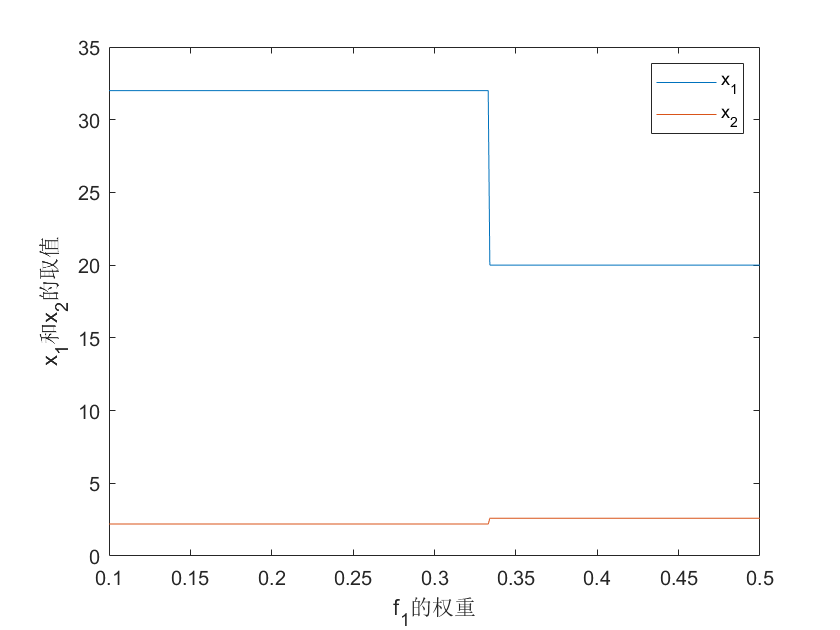


figure(1)
plot(W1,F1,W1,F2)
xlabel('f_{1}的权重')
ylabel('x_{1}和x_{2}的取值')
legend('x_{1}','x_{2}')

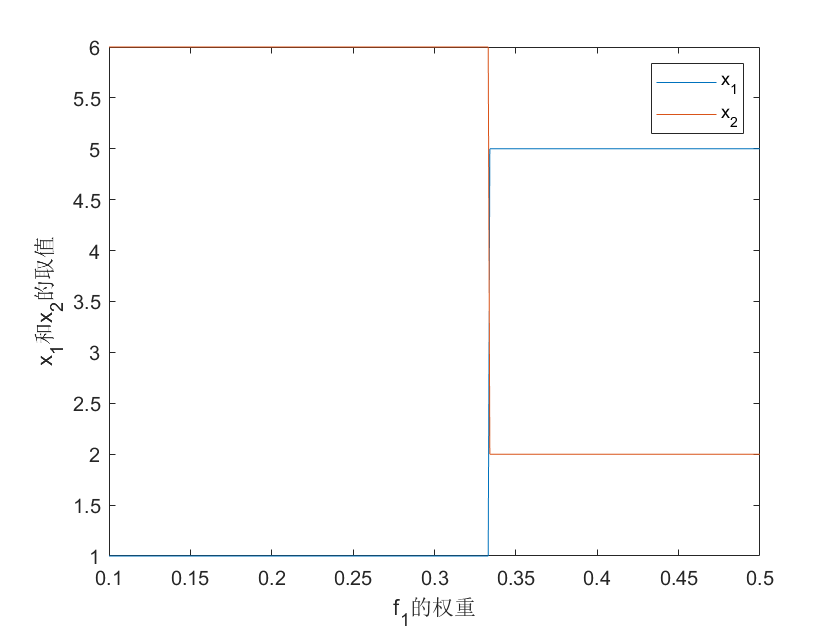


figure(2)
plot(W1,X1,W1,X2)
xlabel('f_{1}的权重')
ylabel('x_{1}和x_{2}的取值')
legend('x_{1}','x_{2}')

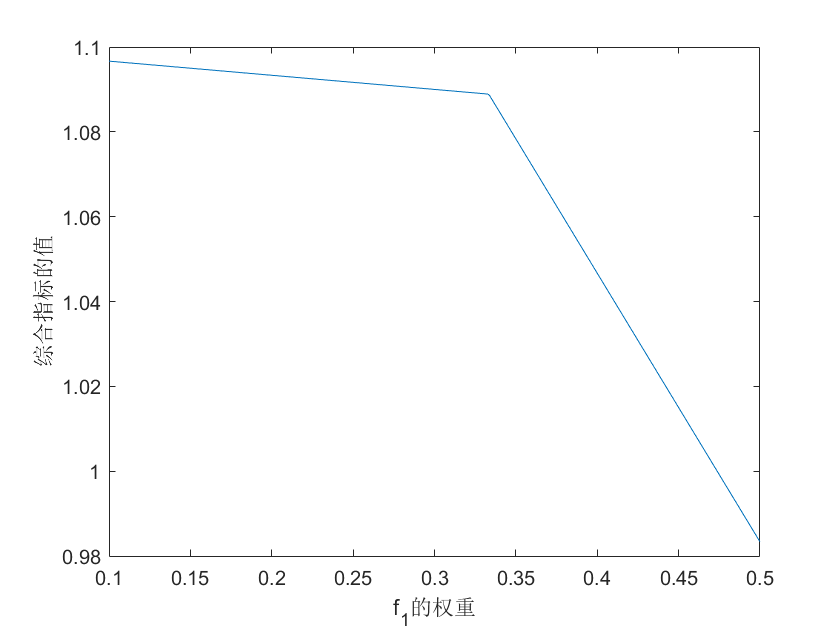


figure(3)
plot(W1,FVAL)
xlabel('f_{1}的权重')
ylabel('综合指标的值')